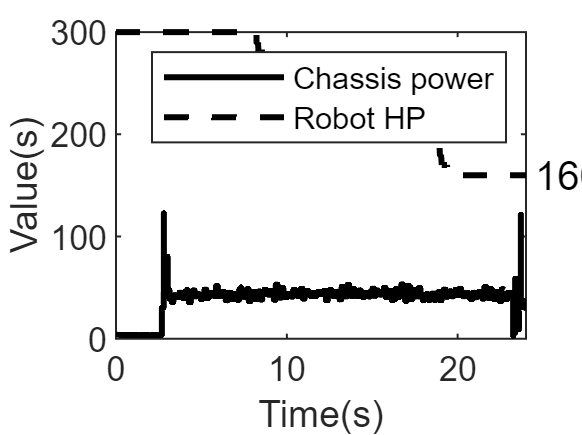


A = datadown4(:, 1:3);
x = (A(:, 1)-1.7134551e12)/10^4; % 横坐标
x = 24 * (x - min(x)) / (max(x) - min(x)); % 将映射到0-24
% figure; % 创建新的图窗
% hold on; % 允许同时绘制多条曲线
for i = 2 % 绘制第2-4列数据
    y = A(:, i); % 纵坐标
        plot(x, y, 'k','LineWidth', 1.5); % 绘制曲线
%     plot(x, y, 'k','LineStyle', '--','LineWidth', 1.5 ,'Marker', 'none', 'MarkerIndices', 1:4:length(y)); % 绘制曲线
    %scatter(x, y, 'filled'); % 绘制散点图
    hold on;
end

for i = 3 % 绘制第2-4列数据
    y = A(:, i); % 纵坐标
    %plot(x, y, 'k','LineWidth', 2); % 绘制曲线
    plot(x, y, 'k','LineStyle', '--','LineWidth', 1.5 ,'Marker', 'none', 'MarkerIndices', 2:8:length(y));
    hold on;
end
% 在HP曲线最后一行添加虚线显示纵坐标值
y_end = y(end);
plot([x(end), x(end)], [y_end, y_end], 'k--'); % 绘制连接曲线末端和横坐标的虚线
text(x(end) + 0.5, y_end, num2str(y_end), 'Color', 'k'); % 添加纵坐标值标签

hold off; % 结束绘图
legend( 'Chassis power','Robot HP'); % 添加图例
xlabel('Time(s)'); % 设置横坐标轴标签
ylabel('Value(s)'); % 设置纵坐标轴标签
xlim([0 24]);
ylim([0 300]);